# **Data Importing and Outputting**

## Importing Data Using the Import Data Button

The easiest way to import larger data sets is to use the 'Import Data' button under the 'Home' tab. Similar to Excel, MATLAB will automatically split the data if it is tab or comma-separated. You can examine the data, edit it, and make changes if necessary. When you are done, click on the 'Import Data' key to the right. Each column of data will be imported as an array with the variable name you specified at the top of the column. 

Click on the arrow below 'Import Data' and note that MATLAB will generate either script code or a function based on your selections in the import data window. That is pretty handy!

## Importing Data using the load command

Load is an easy way to import data if you have text files with columns of numbers, but no text headers.  Download *sunspots*.txt from the Canvas module and run the code below.

load sunspots.txt

Note the data is now loaded into an array with the same variable name.    

You often want to split the columns of loaded data into separate variables.  You can do this using array notation:

%Split data into columns
months=sunspots(:,1);
spots=sunspots(:,2);

%Make a new figure
figure(1);

%Make a plot
plot(months,spots,'k');

%Adjust plot parameters

%Label on vertical axis
ylabel('Number of Sunspots');
xlabel('Months')

%Limits of horizontal axis
xlim([0 3000]);

%gca refers to the axes of the current plot
%Change the font size on the axes to be 18
set(gca,'FontSize',18.);

## Reading Excel data

MATLAB has a special function ([`xlsread`](https://www.mathworks.com/help/matlab/ref/xlsread.html)) for reading in data formatted by Excel (XLS, XLSX, XLSM, XLTX, and XLTM files):

clear all;

%Read in data formatted save in an Excel spreadsheet
capdata=xlsread('capacitor.xlsx');

%Split the columns and save as seperate variables
time=capdata(:,1);
volts=capdata(:,2);

%Make a new figure
figure(1);

%Plot the data as points connected with a thin line
plot(time,volts,'b.',time,volts,'b','MarkerSize',20.,'LineWidth',.3);

%Specify the x and y label, inrease the font size
xlabel('Time (s)','Fontsize',14.);
ylabel('Voltage (V)','Fontsize',14.);

%Specify the title
title('Decaying Capcitor','FontSize',14.);

%gca refers to the axes of the current plot
%Change the font size on the axes to be 14
set(gca,'FontSize',14.);

## Reading Data using [`dlmread`](https://www.mathworks.com/help/matlab/ref/dlmread.html)

The most flexible way to read data is to use dlmread because you can specify whatever delimiter you want.  For example, I use dlmread when reading Cassini data from many flybys.  In the example below, I use a loop to read in and plot data from 4 different Cassini flybys.  Note, that is would not be that difficult for me to plot 100 flybys using the same methodology.

clear all;

%loop over flybys 56 to 59
for flyby=56:59
    
    %Automatically generate the file name and figure name (to be used later)
    %Uses strcat to join (concatenate) strings and num2str to convert number to strings
    filename=strcat('T',num2str(flyby),'_mag');
    figtitle=strcat('T',num2str(flyby),' Magnetic Field Data');

    %Open and read file, specified by the filename
    data=dlmread(filename);
    
    %Convert time values to a datenum (a MATLAB variable type for storing time values)
    date=datenum(data(:,1),data(:,2),data(:,3),data(:,4),data(:,5),data(:,6));
    
    %Extract 3D magnetic field data
    bx=data(:,7);
    by=data(:,8);
    bz=data(:,9);
    
    %Open a new figure
    figure();
    
    %Plot components of magnetic field versus time
    plot(date,bx,date,by,date,bz);
    
    %Label axes
    xlabel('Time (min:sec)');
    ylabel('Magnetic Field (nT)');
    
    %Specify title
    title(figtitle);
    
    %Provide a legend
    legend('B_x','B_y','B_z');
    
    %Change the fontsize and aspect ratio of the axes
    set(gca,'FontSize',13., 'PlotBoxAspectRatio',[1 .3 1]);
    
    %Conver the x-axis tick labels to time minutes and seconds format
    datetick('x','MM:SS','keepticks','keeplimits');
    
    %Set constant limits for the y-axis
    ylim([-12 12]);    
    
end

## **Input from the User**

Getting data from the user is easy in MATLAB (although it is a little awkward in Live Scripts) with the `input` function.  If the data will be a number (integer or float). The prompts appear in the Command Window.

yearborn=input('What year were you born? ')

If you want the user to enter a string (word or characters) you have to be more specific

stringinput=input('What is your first name? ','s')

## **Output to Command Window**

- Can just *not* use a semicolon

- Can use disp, e.g.

disp('hello world')

- OR can use fprintf, which allows the output to be formatted

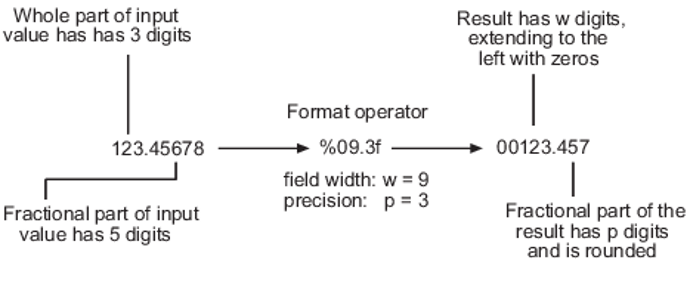

More documentation on formatted output: 

[https://www.mathworks.com/help/matlab/matlab_prog/formatting-strings.html](https://www.mathworks.com/help/matlab/matlab_prog/formatting-strings.html)

### Most commontly used forms:

- %10.4f

- %5d

- %.3e

fprintf('%10.4f float using 10 spaces with 4 decimal places.',exp(1))
fprintf('%5d will use 5 spaces and outputs an integer.',100)
fprintf('%.3e prints in scientific notation with 3 decimal places.',exp(1))

## **Other useful notation:**

- **\n  **

- **%%   ** 

fprintf( 'If you want to drop to a new line after text add \n  See new line. \n')
fprintf('This will give you one %d%% sign.',100)

## Writting a List of Data

`fprintf` can also be used to output a column of values with a specific format.

position = 2:2:10;
time = 1:5;

formatSpec = 'The position of the cart is %6.2f meters at %4.3f s \n';
fprintf(formatSpec,position,time)

That would be a pretty useless way to store data.  It would be better to just print a column header and then the values.  You just have to pay attention to the spacing so everything lines up pretty.

fprintf('%13s %10s\n','Time (s)','Position (m)')
fprintf('%10.1f %10.1f\n',time,position)

## Formatted Output to a File

If you are using MATLAB to do a calculation, you probably want to store the results to a file so you can save them for later.  This is also relatively easy to do.

fileID = fopen('Position Data.txt','w');                  %Open a txt file
fprintf(fileID,'%13s %10s\n','Time (s)','Position (m)');  %Start printing to the file
fprintf(fileID,'%10.1f %10.1f\n',time,position);
fclose(fileID);                                           %Close the file

The data that was printed out above should now be stored in a file in the current folder.  You can include a file path to store the file elsewhere on your computer.

You can use type to view the contents of the file here. This is a nice way to verify that it looks the way you want without opening the file.

type 'Position Data.txt'

The 'w' in the `fopen `command tells MATLAB what permissions to establish for the file it has created.  This can be useful for specifying whether old data should be erased or appended to. Here are the options:

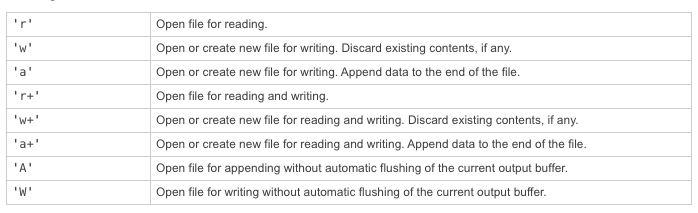

Here is an example where new data is appended to the end of an old file.

fileID = fopen('Position Data.txt','w');                  %Open a txt file
fprintf(fileID,'%13s %10s\n','Time (s)','Position (m)');  %Start printing to the file
fprintf(fileID,'%10.1f %10.1f\n',time,position);
fclose(fileID);    

type 'Position Data.txt'

fileID = fopen('Position Data.txt','a');                  %Open a txt file
fprintf(fileID,'%10.1f %10.1f\n',[6,12],[7,14]);
fclose(fileID);  

type 'Position Data.txt'

## Saving Figures

You can also have MATLAB automatically save plots and other graphics with the `saveas` function. This is useful if you are looping through data an automatically generating a lot of plots that you will examine later.

x = [2 4 7 2 4 5 2 5 1 4];
barplt=bar(x);
saveas(barplt,'Barchart.png')

There are lots of options for the output image format. See the documentation.